## Convolution›: an Illustration

This live script visualizes some of the elements of convolution and deconvolution

1) Convolution: a simple mathematical function that quantifies the similarity between a pattern (a "kernel") such as the red square wave below with data (the blue rectangularish thingy below). The convolution (black line) reflects how similar the blue signal is with the kernel at any given time point. Convolution is thus used in all of digital signal processing. 

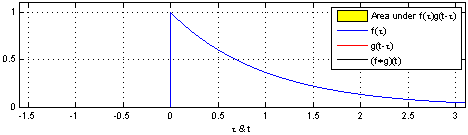

The math is simple. We take the kernel, move it to the first portion of the data by lining it up with the first sample point, then we multiply each element of the kernel with the data, sum the results into one new number and write that to that first sample point. This is the dot-product. 

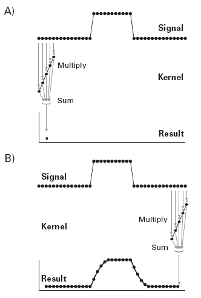

This example is nice but a bit removed from real data. Let's try this with a few more realistic examples. Let's find places in our data, where the signal looks like a single sine wave at 10 Hz. To this end, we need a time range, a signal (data), and a kernel. 

We start by making a discrete time vector, at which the signal will be sampled. 

clear
time = 0.001:0.001:1; % one second of discrete time, sampled at 1000 Hz

now, we make a time series of Brownian noise (biorealistic) time series not unlike EEG/LFP, representing one trial of neural mass data

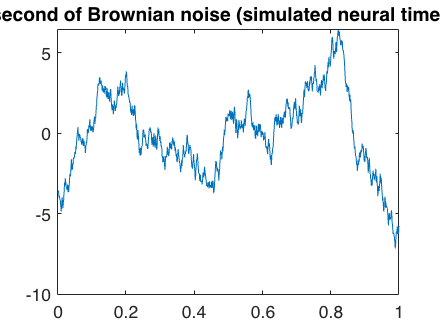

rng(080769) % set random number generator, for repproducibility
temp1 = rand(size(time))-.5; % zero-center the white noise, because we use cumulative sum later
brownsig = cumsum(temp1);  % Brownian noise is the cumulative sum of white noise
brownsig = detrend(brownsig);
figure
plot(time, brownsig),title('One second of Brownian noise (simulated neural time series)') 

Now we make a simple signal, to be added to the brownian noise.

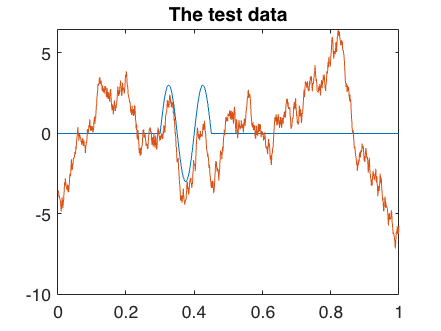

Sin10Hz = sin(2*pi*time*10).*3 ; % a 10 Hz sine wave with 3 µV amplitude
addsig = zeros(size(brownsig)); 
addsig(301:450) = Sin10Hz(301:450);
data1 = brownsig + addsig; 
plot(time, addsig), hold on
plot(time, data1); title('The test data') 

Now we need a kernel, let's take our added signal and see oif we find it! 

kernel = Sin10Hz(301:450); 
kernlength = length(kernel)

kernlength = 150

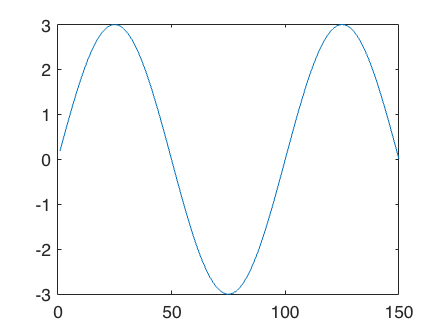

figure, plot(kernel)

Now the convolution. let's do it step by step first, by using the dot product 

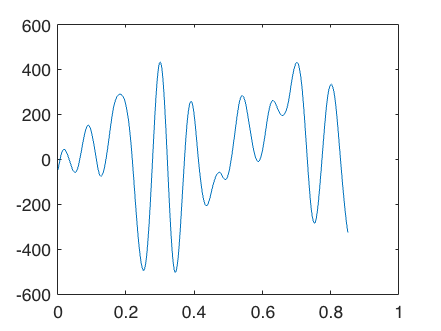

for x = 1:size(data1,2)-kernlength
 convbyhand(x) = data1(x:x+kernlength-1)*kernel'; % the inner product of the kernel, shifted
end
plot(time(1:end-kernlength), convbyhand)

compare this with the built-in convolution function

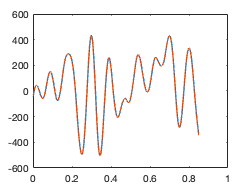

convbuilt = conv(data1, kernel, 'valid');
figure
plot(time(1:end-kernlength), convbyhand), pause(2)
hold on 
plot(time(1:end-kernlength), convbuilt(2:end))

not what you expected ? what happened? let's visualize this in more detail. we run the code above again, and visualize the convolution and the moving kernel. 

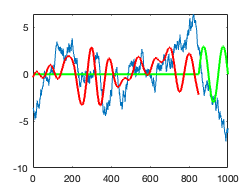


figure
for x = 1:size(data1,2)-kernlength
    convbyhand(x) = data1(x:x+kernlength-1)*kernel';
    plot(data1), hold on
    plot([zeros(1,x) kernel], 'g', 'LineWidth',2),  
    plot(convbyhand(1:x)./150, 'r', 'LineWidth',2), % divide by length of kernel to keep same scale
    pause(.01), hold off 
end

It works as adverized but maybe this is not what we need in many situations! we will talk about this next, in the context of Discrete Fourier Transform. 